load("C:\Users\Asus\Studia\Projekt IPS\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat")

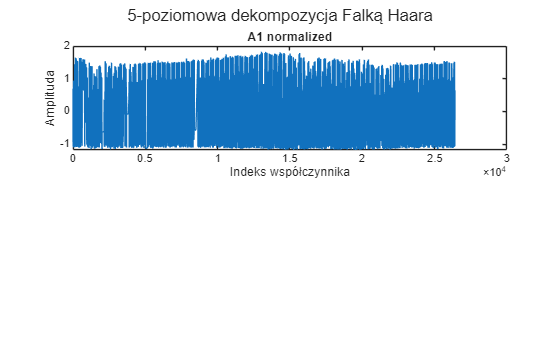

function results_py = model_hybrid(y_train, y_test, step_length,  ma_window, season_period)
    py_model = py.importlib.import_module("model_hybrid");
    results_py = py_model.model_hybrid(...
        y_train, ... 
        y_test, ...
        step_length, ...
        pyargs('ma_window', ma_window, 'season_period', season_period, 'verbose', true) ...
    ).double';
end

function SARIMA_A514 = model_A5(A5)
    A51 = A5(:,1);
    SARIMA_A514 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',[1,2],'SARLags',[21,42],'Seasonality',21,'SMALags',[21,42],'Distribution','Gaussian');
    %SARIMA_A514 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',1:2,'SARLags',[147,294],'Seasonality',147,'SMALags',[147,294],'Distribution','Gaussian');
    SARIMA_A514 = estimate(SARIMA_A514,A51,'Display','off');
end


% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);


% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji A i szczegółów D
A1 = appcoef(c, l, 'haar', 1);
A5 = appcoef(c, l, 'haar', 5);

D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% normalizacja współczynników
[A1_norm, center_A1, scale_A1] = normalize(A1);

% 2. RYSOWANIE WYKRESÓW
figure;

subplot(2, 1, 1);
plot(A1_norm);
title('A1 normalized');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

sgtitle('5-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1_test = appcoef(c_test, l_test, 'haar', 1);
A5_test = appcoef(c_test, l_test, 'haar', 5);

D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

% Normalizacja współczynników testowych
A1_test_norm = (A1_test - center_A1) ./ scale_A1;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

dlugosc_testu_A1 = ceil(dlugosc_testu_oryginalna / 2);

% Przewidywania A1 - model hybrydowy
A1_pred_norm = model_hybrid(A1_norm, A1_test(1:dlugosc_testu_A1), 1, 32, 96*7);

Step: 1 / 1440
Step: 2 / 1440
Step: 3 / 1440
Step: 4 / 1440
Step: 5 / 1440
Step: 6 / 1440
Step: 7 / 1440
Step: 8 / 1440
Step: 9 / 1440
Step: 10 / 1440
Step: 11 / 1440
Step: 12 / 1440
Step: 13 / 1440
Step: 14 / 1440
Step: 15 / 1440
Step: 16 / 1440
Step: 17 / 1440
Step: 18 / 1440
Step: 19 / 1440
Step: 20 / 1440
Step: 21 / 1440
Step: 22 / 1440
Step: 23 / 1440
Step: 24 / 1440
Step: 25 / 1440
Step: 26 / 1440
Step: 27 / 1440
Step: 28 / 1440
Step: 29 / 1440
Step: 30 / 1440
Step: 31 / 1440
Step: 32 / 1440
Step: 33 / 1440
Step: 34 / 1440
Step: 35 / 1440
Step: 36 / 1440
Step: 37 / 1440
Step: 38 / 1440
Step: 39 / 1440
Step: 40 / 1440
Step: 41 / 1440
Step: 42 / 1440
Step: 43 / 1440
Step: 44 / 1440
Step: 45 / 1440
Step: 46 / 1440
Step: 47 / 1440
Step: 48 / 1440
Step: 49 / 1440
Step: 50 / 1440
Step: 51 / 1440
Step: 52 / 1440
Step: 53 / 1440
Step: 54 / 1440
Step: 55 / 1440
Step: 56 / 1440
Step: 57 / 1440
Step: 58 / 1440
Step: 59 / 1440
Step: 60 / 1440
Step: 61 / 1440
Step: 62 / 1440
Step: 63 / 1440
S

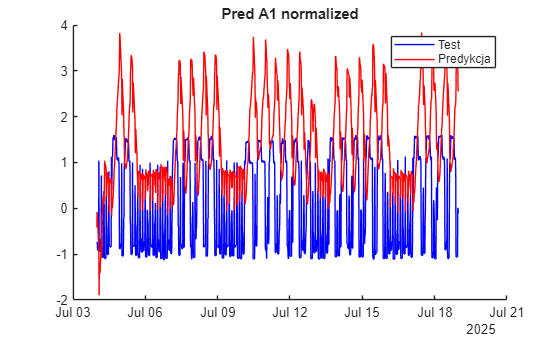

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_A1), A1_test_norm(1:dlugosc_testu_A1), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_A1), A1_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred A1 normalized');
legend;

% DENORMALIZACJA
% Odwracamy proces: x = y * scale + center
A1_pred = (A1_pred_norm .* scale_A1) + center_A1;

D1_pred = zeros(length(A1_pred),1)';

final_prediction = idwt(A1_pred, D1_pred,'haar');      % podejście: A1 hybryda

y_test = ab_diff_test_norm(1:length(final_prediction))';

mae_score = mae(y_test, final_prediction)

mae_score = 0.5595

mape_score = mape(y_test, final_prediction)

mape_score = 69.6356

rmse_score = rmse(y_test, final_prediction)

rmse_score = 0.6963

r2_classic = R2_classic(y_test, final_prediction)

r2_classic = -3.0454

r2_alt = R2_alt(y_test, final_prediction)

r2_alt = 2.6989

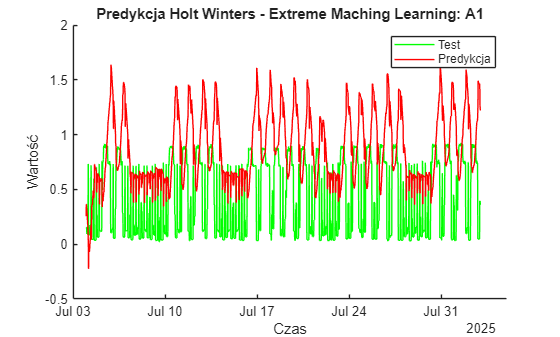


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(final_prediction)), ab_diff_test_norm(1:length(final_prediction)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(final_prediction)), final_prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters - Extreme Maching Learning: A1")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   sum_of_4_signals_test(1:dlugosc_testu_oryginalna), ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, 'pred_ab_A1_HYBRYDA_1_month.xlsx');